# Satélite en órbita alrededor de la Tierra

Un satélite orbitando la Tierra, la Tierra está en el origen (inicialmente). El satélite tiene una masa de 20 toneladas y se encuentra a 108 km de altura (eje x). Los vectores tienen los datos [tierra, satélite].


$$\begin{array}{l}
y=\left\lbrack \begin{array}{c}
r\\
v
\end{array}\right\rbrack \\
\mathrm{y'}=\left\lbrack \begin{array}{c}
v\\
a
\end{array}\right\rbrack \\
\frac{\textrm{d}}{\textrm{d}t}y=f\left(t,y\right)
\end{array}$$


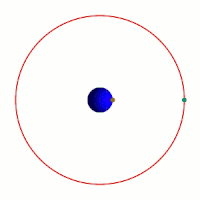

Solución para Satélite y Tierra. Tomamos como posición inicial la Tierra y el satélite solo cambia la altura a la que esta del centro de la Tierra.

## Explicacion del algoritmo

Utilizamos la función de Ley Gravitacional con los datos reales de la masa de la Tierra, el satelite. El radio de la Tierra, la altura del satelite a la superficie de la Tierra.

Para guardar las posiciones de la Tierra y el satelite, se crea una matriz de 3000 x 6. En la cual cada columna se representa un tiempo t. Las filas 1 a 3 corresponden a la posicion de la Tierra en x,y,z. Las filas 4 a 6 corresponden a las posiciones del satelite en x,y,z.

global G m;
G = 6.67408E-11;              % m3 kg-1 s-2
mT = 5.9736E+24;              % masa de la Tiera
ms = 20000;                   % masa del satélite
m = [mT, ms];

En esta parte se declaran variables globales, estas son:

G: constante gravitatoria

mT: es la masa de la Tierra en kilogramos.

ms: es la masa del satélite en kg.

rT = 6371e3;                       
hs = 35786000;                     
r0 = [ [0;0;0], [rT+hs;0;0] ];     
vs = sqrt(G * m(1)/r0(1,2));       
v0 = [ [0;0;0], [0;vs;0] ];        

Se definen los valores rT, hs, r0, vs,v0

rT: El radio de la Tierra

hs: la altura del satelite con respecto a l superficie de la Tierra, no de el centro de la Tierra

r0: es un vector 3x2 que contiene las posiciones iniciales de la Tierra en la primera columna y las del satelite en la segunda columna.

vs:

v0:

ws = vs/(rT+hs);  

T = (2*pi)/ws; 
h = 60;        
nv = 4;
Nk = nv*ceil(T/h);   

pos = zeros(6,Nk+1);       

pos(:,1) = [r0(:,1);r0(:,2)];  

y = [r0;v0];    


for t=2:Nk+1
    s1 = f(t,y);
    s2 = f(t+h/2,y+(h/2)*s1);
    s3 = f(t+h/2,y+(h/2)*s2);
    s4 = f(t+h, y+h*s3);
    slope = (s1+2*s2+2*s3+s4)/6;
    
    y = y + slope*h;        
    
    r = y(1:3,:);          
    
    pos(:,t) = [r(:,1);r(:,2)];
   
end


Se utliza el método RK4

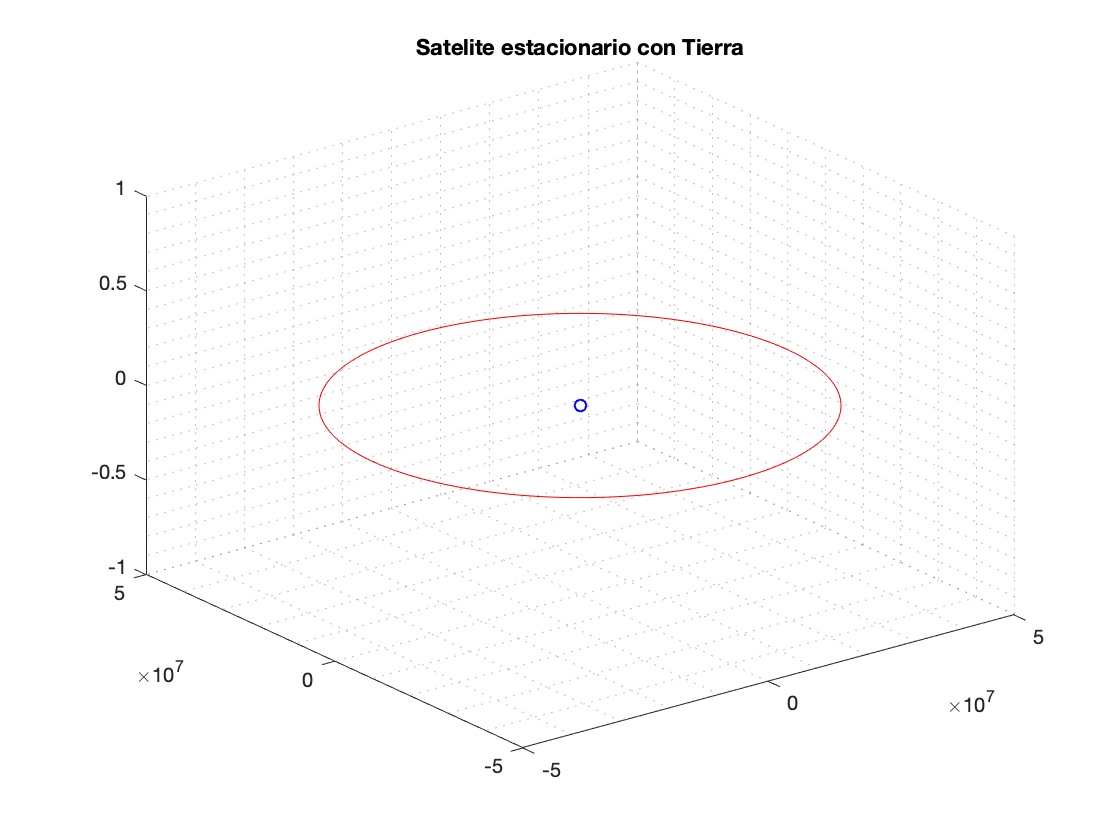

plot3(pos(1,:),pos(2,:),pos(3,:),'ob');
hold on;
plot3(pos(4,:),pos(5,:),pos(6,:),'r');
grid minor;
title('Satelite estacionario con Tierra')
hold off

## Tierra y Luna

Solución para la relación Luna y Tierra tomando como referencia el centro de la Tierra.

global G m;
G = 6.67408E-11;             
mT = 5.9736E+24;            
mS = 7.349E+22;                
m = [mT, mS];

rT = 6371e3;                        
dTs = 384400000;                    
rS = 1737100;                        
r0 = [ [0;0;0], [rT+dTs+rS;0;0] ];    
vT = sqrt(G * m(1)/r0(1,2));       
v0 = [ [0;0;0], [0;vT;0] ];        

ws = vT/(rT+dTs);                 

T = (2*pi)/ws;                     
h = 300;                             
nv = 4;
Nk = nv*ceil(T/h);  

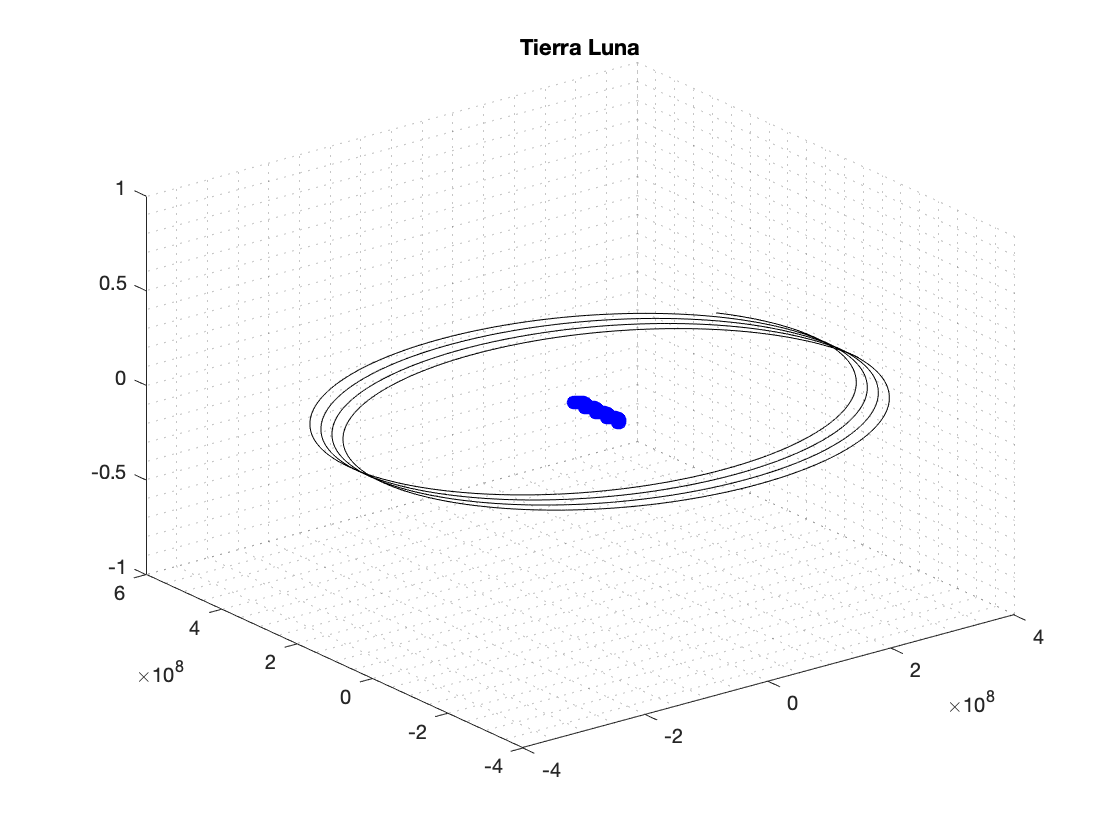

pos = zeros(6,Nk+1);      

pos(:,1) = [r0(:,1);r0(:,2)];       

y = [r0;v0];

for t=2:Nk+1
    s1 = f(t,y);
    s2 = f(t+h/2,y+(h/2)*s1);
    s3 = f(t+h/2,y+(h/2)*s2);
    s4 = f(t+h, y+h*s3);
    slope = (s1+2*s2+2*s3+s4)/6;
    y = y + slope*h;            
    
    r = y(1:3,:);               

    pos(:,t) = [r(:,1);r(:,2)];    
end

plot3(pos(1,:),pos(2,:),pos(3,:),'ob');
hold on;
plot3(pos(4,:),pos(5,:),pos(6,:),'k');
title('Tierra Luna')
grid minor;
hold off

## Solución de un sistema de tres variables

## Venus, Tierra y el Sol. 

## Tomando al sol como la referencia

% global G m;
% G = 6.67408E-11;   
% mT = 5.9736E+24;   
% mL = 4.867E+24;    
% mS = 1.989E+30;    
% m = [mS, mT, mL];

% rT = 6371e3;       
% rL = 6051800;      
% rS = 695510000;    
% dTS = 149600000000;
% dSV = 108200000000;
% r0 = [[0;0;0], [rS+dTS+rT;0;0],[rS+dSV+rL;0;0]];
% vT = sqrt(G * m(1)/r0(1,2));        
% vL = sqrt(G * m(1)/r0(1,3));        
% v0 = [ [0;0;0], [0;vT;0] , [0;vL;0]];

% wsT = vT/(rS+dTS);                  
% T = (2*pi)/wsT;                     
% h = 3600;                          
% nv = 4;
% NktT = nv*ceil(T/h);                    
% 
% wsV = vL/(rS+dSV);
% 
% Tl = (2*pi)/wsV;
% NktV = nv*ceil(Tl/h);
% 

% 
% pos = zeros(9,NktT+1);               
% pos(:,1) = [r0(:,1);r0(:,2);r0(:,3)];       
% 
% y = [r0(:,1), r0(:,2); v0(:,1),v0(:,2)];    
% z = [r0(:,1), r0(:,3); v0(:,1),v0(:,3)];    
% 
% for t=2:NktT+1
%     s1 = f(t,y);
%     s2 = f(t+h/2,y+(h/2)*s1);
%     s3 = f(t+h/2,y+(h/2)*s2);
%     s4 = f(t+h, y+h*s3);
%     slope = (s1+2*s2+2*s3+s4)/6;
%     y = y + slope*h; 
%     
%     z1 = f(t,z);
%     z2 = f(t+h/2,z+(h/2)*z1);
%     z3 = f(t+h/2,z+(h/2)*z2);
%     z4 = f(t+h, z+h*z3);
%     zlope = (z1+2*z2+2*z3+z4)/6;          
%     z = z + zlope*h;
%     
%     r = [y(1:3,:), z(1:3,2)];                
%    
%     pos(:,t) = [r(:,1);r(:,2);r(:,3)];
% 
% end
% 
% plot3(pos(1,:),pos(2,:),pos(3,:),'sk');
% hold on;
% plot3(pos(4,:),pos(5,:),pos(6,:),'.g');
% plot3(pos(7,:),pos(8,:),pos(9,:),'.r');
% grid minor;
% title('Sol, Tierra, Venus')

## Sol, Tierra, Venus 2

global G m;
G = 6.67408E-11;   
mT = 5.9736E+24;   
mV= 4.867E+24;    
mS = 1.989E+30;    
m = [mS, mT, mV];

Se declaran las variables globales G y m.

G: es la constante gravitatoria

rT = 6371e3;       
rL = 6051800;      
rS = 695510000;    
dTS = 149600000000;
dSV = 108200000000;
r0 = [[0;0;0], [rS+dTS+rT;0;0],[rS+dSV+rL;0;0]];
vT = sqrt(G * m(1)/r0(1,2));        
vV = sqrt(G * m(1)/r0(1,3));        
v0 = [ [0;0;0], [0;vT;0] , [0;vL;0]];

wsT = vT/(rS+dTS);                  
T = (2*pi)/wsT;                     
h = 3600;                          
nv = 4;
NktT = nv*ceil(T/h);                    

wsV = vV/(rS+dSV);
Tl = (2*pi)/wsV;
NktV = nv*ceil(Tl/h);


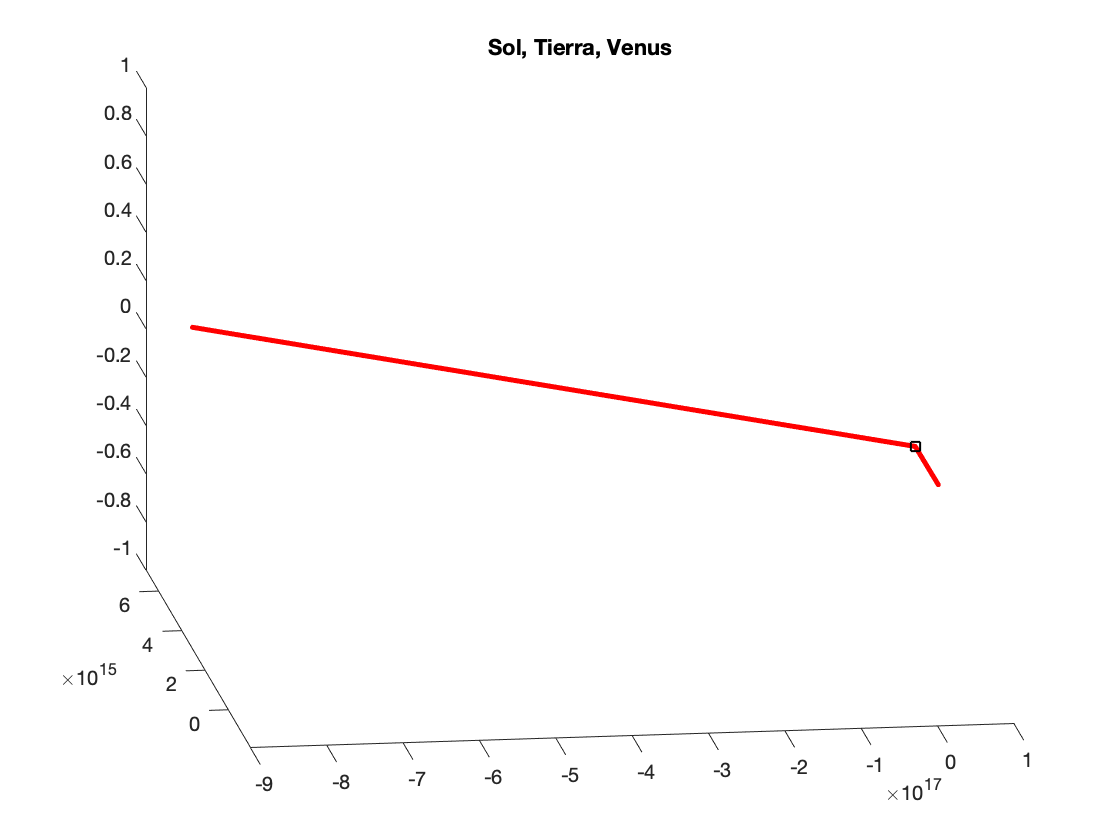

pos = zeros(9,NktT+1);               
pos(:,1) = [r0(:,1);r0(:,2);r0(:,3)];       

y = [r0(:,1), r0(:,2), r0(:,3); v0(:,1),v0(:,2),v0(:,3)];    
   

for t=2:NktT+1
    s1 = f3(t,y);
    s2 = f3(t+h/2,y+(h/2)*s1);
    s3 = f3(t+h/2,y+(h/2)*s2);
    s4 = f3(t+h, y+h*s3);
    slope = (s1+2*s2+2*s3+s4)/6;
    y = y + slope*h; 
    
    r = [y(1:3,:)];                
   
    pos(:,t) = [r(:,1);r(:,2);r(:,3)];

end

plot3(pos(1,:),pos(2,:),pos(3,:),'sk');
hold on;
plot3(pos(4,:),pos(5,:),pos(6,:),'.g');
plot3(pos(7,:),pos(8,:),pos(9,:),'.r');
grid minor;
title('Sol, Tierra, Venus')

## SOL, TIERRA, LUNA

% global G m;
% G = 6.67408E-11;
% mT = 5.9736E+24;
% mL = 7.349E+22;
% mS = 1.989E+30;
% m = [mS, mT, mL];
% 
% rT = 6371e3;
% rL = 1737100;
% rS = 695510000;
% dTS = 149600000000;
% dTL = 1737100;

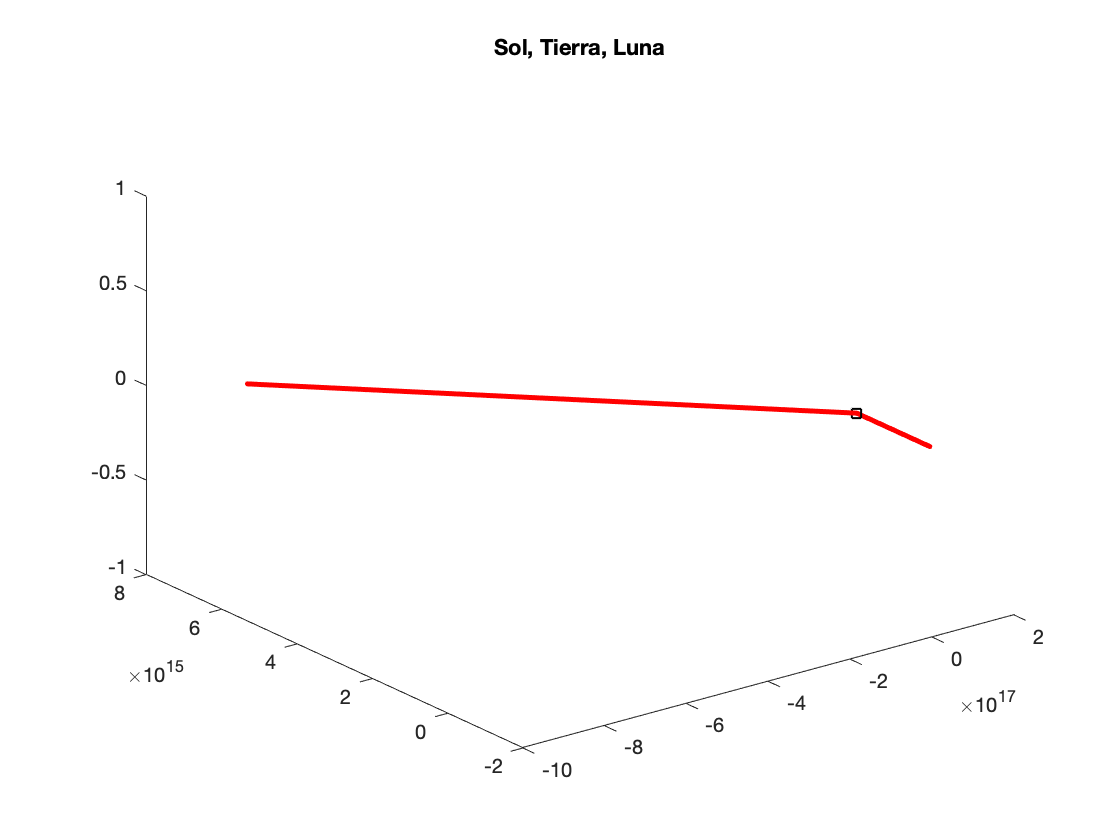

% r0 = [[0;0;0], [rS+dTS+rT;0;0],[rS+dTS+rT+dTL+rL;0;0]];
% vT = sqrt(G * m(1)/r0(1,2));
% vL = sqrt(G * m(2)/r0(1,3));
% v0 = [ [0;0;0], [0;vT;0] , [0;vL;0]];
% 
% wsT = vT/(rS+dTS);                  
% T = (2*pi)/wsT;                     
% h = 3600;                          
% nv = 4;
% NktT = nv*ceil(T/h);                    
% 
% wsV = vL/(rT+dTL);
% 
% Tl = (2*pi)/wsV;
% NktV = nv*ceil(Tl/h);
% 
% pos = zeros(9,NktT+1);               
% pos(:,1) = [r0(:,1);r0(:,2);r0(:,3)];       
% 
% y = [r0(:,1), r0(:,2); v0(:,1),v0(:,2)];    
% z = [r0(:,2), r0(:,3); v0(:,2),v0(:,3)];    
% 
% 
% for t=2:NktT+1
%     s1 = f(t,y);
%     s2 = f(t+h/2,y+(h/2)*s1);
%     s3 = f(t+h/2,y+(h/2)*s2);
%     s4 = f(t+h, y+h*s3);
%     slope = (s1+2*s2+2*s3+s4)/6;
%     y = y + slope*h; 
%     
%     z1 = f(t,z);
%     z2 = f(t+h/2,z+(h/2)*z1);
%     z3 = f(t+h/2,z+(h/2)*z2);
%     z4 = f(t+h, z+h*z3);
%     zlope = (z1+2*z2+2*z3+z4)/6;          
%     z = z + zlope*h;
%     
%     r = [y(1:3,:), z(1:3,2)];                
%    
%     pos(:,t) = [r(:,1);r(:,2);r(:,3)];
% 
% end
% 
% plot3(pos(1,:),pos(2,:),pos(3,:),'sk');
% hold on;
% plot3(pos(4,:),pos(5,:),pos(6,:),'.g');
% plot3(pos(7,:),pos(8,:),pos(9,:),'.r');
% grid minor;
% title('Sol, Tierra, Luna')

# SOL, TIERRA, LUNA

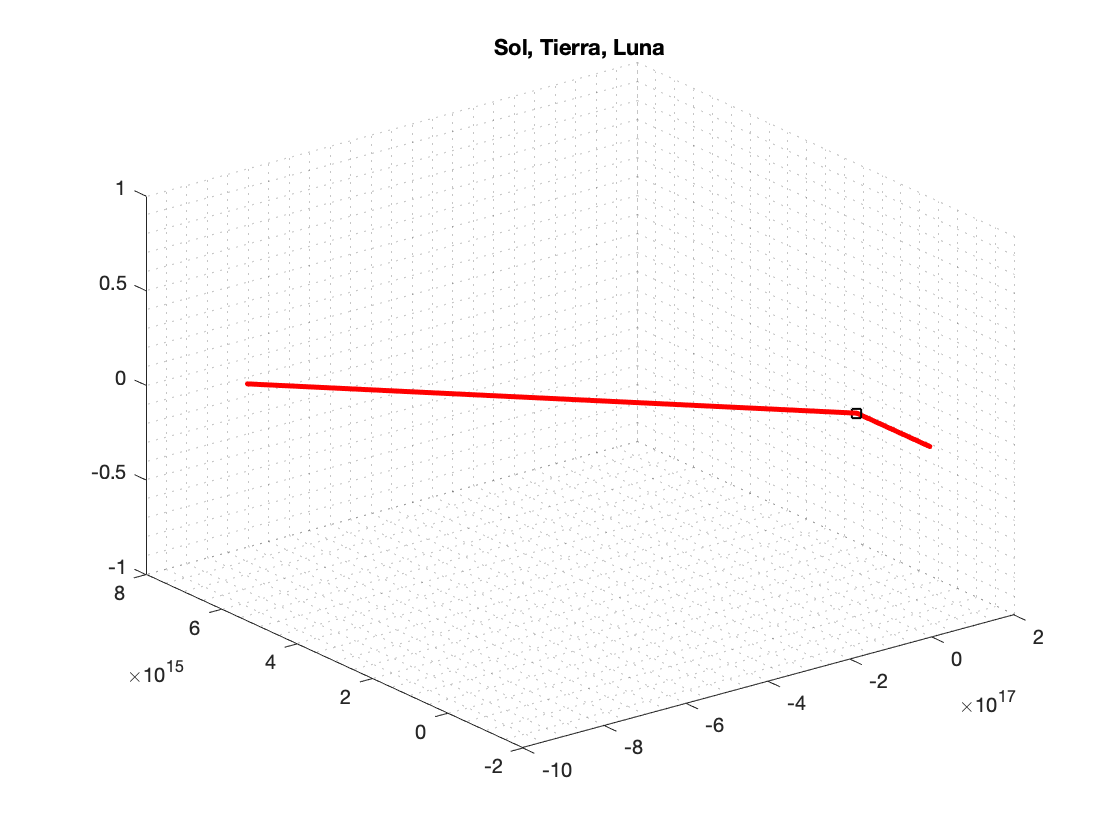

global G m;
G = 6.67408E-11;
mT = 5.9736E+24;
mL = 7.349E+22;
mS = 1.989E+30;
m = [mS, mT, mL];

rT = 6371e3;
rL = 1737100;
rS = 695510000;
dTS = 149600000000;
dTL = 1737100;

r0 = [[0;0;0], [rS+dTS+rT;0;0],[rS+dTS+rT+dTL+rL;0;0]];
vT = sqrt(G * m(1)/r0(1,2));
vL = sqrt(G * m(2)/r0(1,3));
v0 = [ [0;0;0], [0;vT;0] , [0;vL;0]];

wsT = vT/(rS+dTS);                  
T = (2*pi)/wsT;                     
h = 3600;                          
nv = 4;
NktT = nv*ceil(T/h);                    

wsV = vL/(rT+dTL);

Tl = (2*pi)/wsV;
NktV = nv*ceil(Tl/h);

pos = zeros(9,NktT+1);               
pos(:,1) = [r0(:,1);r0(:,2);r0(:,3)];       

y = [r0(:,1), r0(:,2),r0(:,3); v0(:,1),v0(:,2),v0(:,3)];      

for t=2:NktT+1
    s1 = f3(t,y);
    s2 = f3(t+h/2,y+(h/2)*s1);
    s3 = f3(t+h/2,y+(h/2)*s2);
    s4 = f3(t+h, y+h*s3);
    slope = (s1+2*s2+2*s3+s4)/6;
    y = y + slope*h; 
    
    r = [y(1:3,:)];                
   
    pos(:,t) = [r(:,1);r(:,2);r(:,3)];
    
end

plot3(pos(1,:),pos(2,:),pos(3,:),'sk');
hold on;
plot3(pos(4,:),pos(5,:),pos(6,:),'.g');
plot3(pos(7,:),pos(8,:),pos(9,:),'.r');
grid minor;
title('Sol, Tierra, Luna')

## Funcion de calculo de velocidad y aceleración

function ydot = f(~,y)
global G m;
r = y(1:3,:);
v = y(4:6,:);
dr = r(:,2) - r(:,1);
u = dr / norm(dr);
dr2 = norm(dr)^2;
F = (G*m(1)*m(2)/dr2) * u;
a = [F/m(1), - F/m(2)];
ydot = [v;a];
end

function ydot = f2(~,y)
global G m;
r = y(1:3,:);
v = y(4:6,:);
dr2 = r(:,2) - r(:,1);
dr3 = r(:,3) - r(:,1);

u2 = dr2 / norm(dr2);
u3= dr3 / norm(dr3);

dr12 = norm(dr2)^2;
dr32 = norm(dr3)^2;

FsT= (G*m(1)*m(2)/dr12) * u2;
FsV= (G*m(1)*m(3)/dr32) * u3;
Fs = FsT + FsV;

a = [Fs/m(1), - Fs/m(2), -Fs/m(3)];
ydot = [v;a];
end


function ydot = f3(~,y)
global G m;
r = y(1:3,:);
v = y(4:6,:);
dr1 = r(:,2) - r(:,1);
dr3 = r(:,3) - r(:,1);

u = dr1 / norm(dr1);
u3= dr3 / norm(dr3);

dr12 = norm(dr1)^2;
dr32 = norm(dr3)^2;

FsT= (G*m(1)*m(2)/dr12) * u;
FsV= (G*m(1)*m(3)/dr32) * u3;
Fs = FsT + FsV;

a = [Fs/m(1), - Fs/m(2), -Fs/m(3)];
ydot = [v;a];
end